process_node = ros2node('matlab/process_img'); 
img_sub = ros2subscriber(process_node , '/coppelia/camera/image', 'sensor_msgs/Image')

img_msg = img_sub.receive(); % Get the sensor_msgs/Image 
img = rosReadImage(img_msg);

**Note:** The rosReadImage method takes the properties from the img_msg and reconstructs into a uin8 multiarray format that matlab can understand. For the transport layer, is used a 1-array format. 

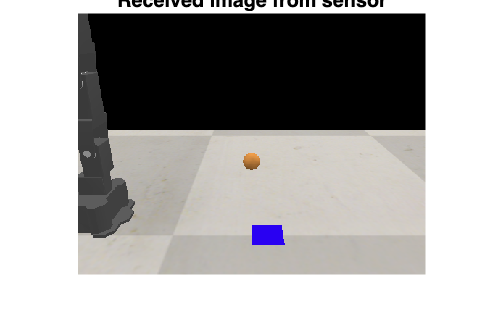

imshow(img); title("Received image from sensor")